% example13: spatial difference
clear;

## Problem specification

% x in [-M,M], x_0=-M, x_{N}=M Due to periodic boundary conditions we don't need x_0
N = 100; 
h = 2*pi/(N); 
xgrid = -pi+h:h:pi;
M = pi;

% phi = @(x) -cos(x); true = @(x) cos(x);
% phi = @(x) cos(2*x); true = @(x) -4*cos(2*x);
% phi = @(x) sin(10*x); true = @(x) -100*sin(10*x);
phi = @(x) x.^2; true = @(x) 2;

% figure(); 
% plot(xgrid,phi(xgrid),'kx','LineWidth',2);

% first order
h = 2*pi/N; x = -pi + (1:N)'*h; % (A) WHAT IS HAPPENING HERE?
firstcol = [0 -1 zeros(1,N-2)]'; 
firstrow = [0 1 zeros(1,N-2)];

SD = toeplitz(firstcol,firstrow);
SD(1,N) = -1;
SD(N,1) = 1;    % modifications to make differencing periodic
SD = SD/(2*h);
SD2 = SD*SD;    % second derivative using repeated first derivatives
errSD = SD2*phi(x) - true(x);

% second order
firstcol = [-2 1 zeros(1,N-2)]'; 
firstrow = [-2 1 zeros(1,N-2)];

TD = toeplitz(firstcol,firstrow);
TD(1,N) = 1;
TD(N,1) = 1; % modifications to make differencing periodic
TD = TD/h/h;
errTD = TD*phi(x)-true(x);

% spectral differentiation
h = 2*pi/N;
x = -pi + (1:N)'*h;
column = [0 .5*(-1).^(1:N-1).*cot((1:N-1)*h/2)];
SpecD = toeplitz(column,column([1 N:-1:2]));
SpecD = SpecD*SpecD;
errSpecD = SpecD*phi(x)-true(x);

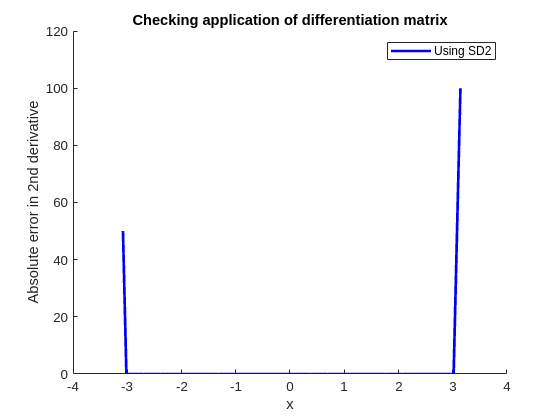

% plotting

figure();
xlabel('x'); 
ylabel('Absolute error in 2nd derivative');
title('Checking application of differentiation matrix');

hold on;
plot(x,abs(errSD),'b','LineWidth',2);
% plot(x,abs(errTD),'g','LineWidth',2);
% plot(x,abs(errSpecD),'r', 'LineWidth', 2);
legend('Using SD2', 'Using TD', 'Using spectral');

% Test on Poisson problem u''= f with periodic BC

% f = @(x) sin(x); % true solution is -sin(x) + C
f = @(x) exp(-(x.^2)/100);

usd2 = SD2\f(x);

ut = TD\f(x);

uspec = SpecD\f(x);

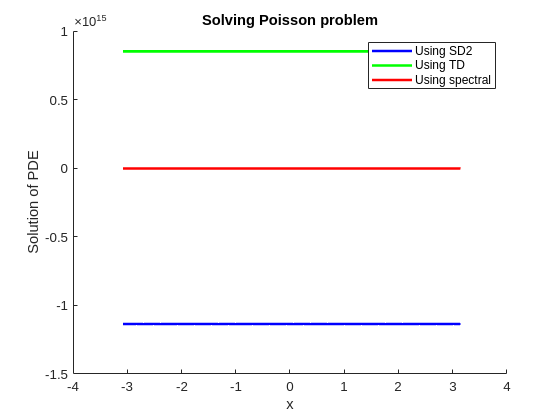


figure();
xlabel('x');
ylabel('Solution of PDE');
title('Solving Poisson problem');

hold on;
plot(x,usd2,'b','LineWidth',2);     % using SD2  
plot(x,ut,'g','LineWidth',2);       % using TD
plot(x,uspec,'r','LineWidth',2);    % using Spectral
legend('Using SD2', 'Using TD', 'Using spectral');